# What is the role of temperature?

Temperature effects biological and chemical systems, and neurons are no exception. How exactly temperature affects the dynamics needs to be built into the model; for example, sometimes you might see the calcuation of a $Q_{10}$ value (see e.g. [here](https://en.wikipedia.org/wiki/Q10_(temperature_coefficient))).

Let's explore the role of temperature on the Hodgkin-Huxley model, as implemented in NEURON.

## Get started

To get started we must create our NEURON object and load `stdrun.hoc`. Just to be safe, we'll also clear all MATLAB values and discard any existing sections.

clear;
n = neuron.Neuron();            % Initialize the NEURON session.
n.reset_sections();             % Reset topology.
n.load_file("stdrun.hoc");      % load the standard run control

An obvious question before we get started is: "what is NEURON's default temperature"? We can find out by checking the value of `n.celsius`:

n.celsius

ans = 6.3000

Wow, that's certainly much colder than a mammalian cell. We'll have to remember to change that if we simulate humans or mice.

## The model

We'll use a simple point cell model with Hodgkin-Huxley dynamics and a current clamp injection.

soma = n.Section("soma");
soma.length = 10;
soma.set_diameter(10);

As an aside, if it seems odd that we're specifying the soma as a cylinder of length 10 and diameter 10 microns, remember that if there's one compartment and only electrophysiology (e.g. no reaction-diffusion), all that matters is the membrane area, and:


$${\textrm{Area}}_{\textrm{cylinder}} \left(L,d\right)=\pi \;d\;L$$



$${\textrm{Area}}_{\textrm{sphere}\left(\right.} \left(d\right)=4\pi \;{\left(\frac{d}{2}\right)}^2 =\pi \;d^2$$


and thus


$${\textrm{Area}}_{\textrm{cylinder}} \left(10,10\right)=100\;\pi ={\textrm{Area}}_{\textrm{sphere}} \left(10\right)$$


That is, the soma here will behave exactly as a sphere of diameter 10 microns.

Let's add the ion channels:

soma.insert("hh");

and setup a current clamp injection:

ic = n.IClamp(soma(0.5));
ic.del = 1;    % ms
ic.dur = 0.1;  % ms
ic.amp = 0.5;  % nA

## Instrumentation

We'll create vectors to record time and membrane potential:

t = n.Vector();
t.record(n.ref("t"));
v = n.Vector();
v.record(soma(0.5).ref("v"));

## Test

We'll test by running this twice, once at 6.3 C and once with a temperature of 10 degrees C. We'll plot both on the same graph by using `hold on`.

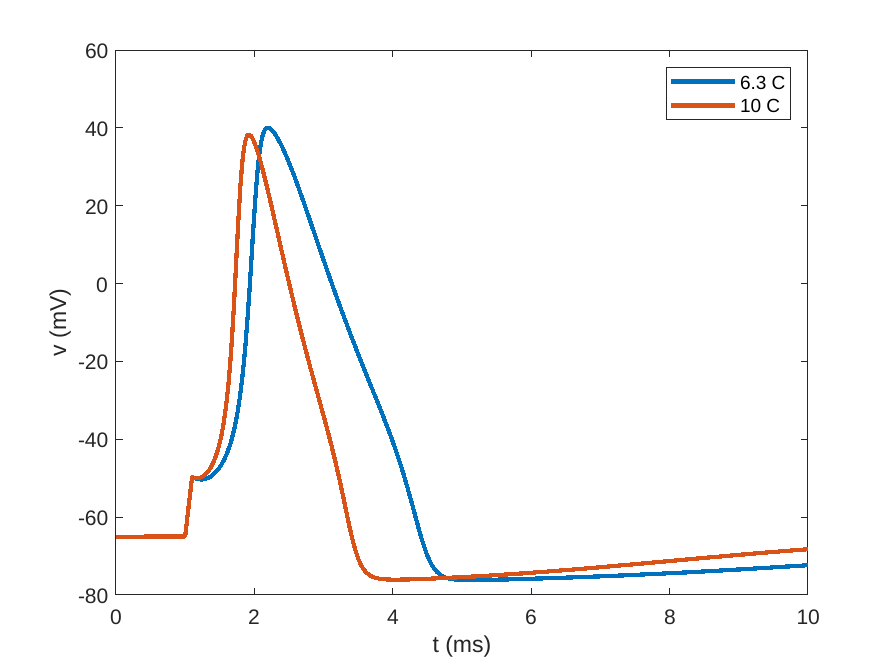

n.celsius = 6.3;
n.finitialize(-65);
n.continuerun(10);
plot(t.data(), v.data(), "linewidth", 2);
hold on;
n.celsius = 10;
n.finitialize(-65);
n.continuerun(10);
plot(t.data(), v.data(), "linewidth", 2);  % in Python, you would just use t and v... could do the same here,
                           % but it would be slower
xlabel("t (ms)");
ylabel("v (mV)");
legend('6.3 C', '10 C');
n.celsius = 6.3;  % restoring the default value
hold off;         % display the final result

We note that even this shift of less than 4 C causes the action potential to spike visibly earlier and significantly shortens the half-width.

## Dynamic exploration of temperature

Instead of using a hard-coded value, we can use a control set to rerun the code section whenever its value is changed.

n.celsius =6;

Drag the slider and watch as the graph changes:

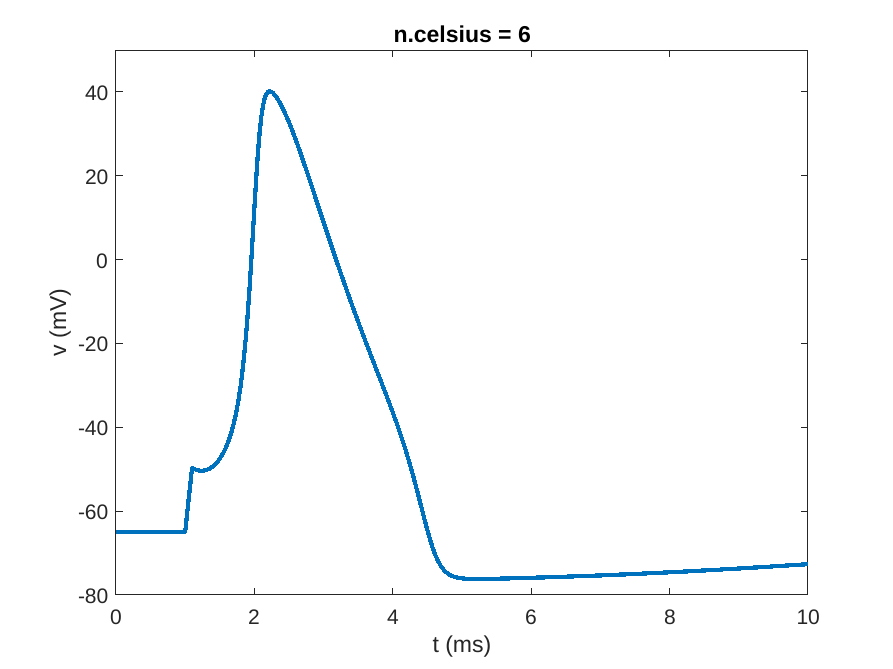

n.finitialize(-65);
n.continuerun(10);
plot(t.data(), v.data(), "linewidth", 2);
xlabel('t (ms)');
ylabel('v (mV)');
ylim([-80 50]);  % fixed ylim so consistent each time
title("n.celsius = " + n.celsius);

n.celsius = 6.3;  % we changed something from the defaults
                  % so let's put it back